clc; clear;
dsFolder = "p_dataset_26";
subFolder = ["0", "4", "7", "8", "A", "D", "H"];
categories = ["0", "4", "7", "8", "A", "D", "H"];

allData = table('Size', [0, 2], 'VariableTypes', {'cell', 'cell'}, 'VariableNames', {'Image', 'Label'});

desiredSize = [224, 224]; % Set your desired image size

for i = 1:length(subFolder)
    folderPath = fullfile(dsFolder, subFolder(i));
    pngFiles = dir(fullfile(folderPath, "*.png"));

    for j = 1:length(pngFiles)
        pngFilePath = fullfile(folderPath, pngFiles(j).name);
        image = imread(pngFilePath);
        
        % Resize or pad the image to the desired size
        % resizedImage = imresize(image, desiredSize);
        % Alternatively, use padarray to add padding
        % paddedImage = padarray(image, [desiredSize(1)-size(image,1), desiredSize(2)-size(image,2)], 0, 'post');
        
        % Store the resized/padded image and label
        allData = [allData; {image, categories(i)}];
        
%         allData = [allData; {image, categories(i)}];
    end
end

% define images & labels
numImages = size(allData, 1);
imageSize = size(allData.Image{1});
images = zeros(imageSize(1), imageSize(2), 1, numImages);

for i = 1:numImages
    images(:, :, 1, i) = allData.Image{i};
end

labels = categorical(allData.Label);

% split data into train and test set
cv = cvpartition(labels, 'HoldOut', 0.25);
trainIdx = training(cv);
testIdx = test(cv);
trainImages = images(:, :, :, trainIdx);
trainLabels = labels(trainIdx);
testImages = images(:, :, :, testIdx);
testLabels = labels(testIdx);

% Define the layers of the CNN
layers = [
    imageInputLayer([imageSize 1])

    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    fullyConnectedLayer(numel(categories))
    softmaxLayer
    classificationLayer
    ];

% Training options
options = trainingOptions( ...
    'sgdm', ... % Stochastic Gradient Descent with Momentum
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |       18.75% |       38.06% |       2.5563 |       7.0497 |          0.0100 |
|       3 |          30 |       00:00:23 |       89.06% |       88.96% |       0.5235 |       0.4020 |          0.0100 |
|       5 |          50 |       00:00:33 |       89.84% |              |       0.3650 |              |          0.0100 |
|       6 |          60 |       00:00:41 |       96.88% |       93.47% |       0.1193 |   

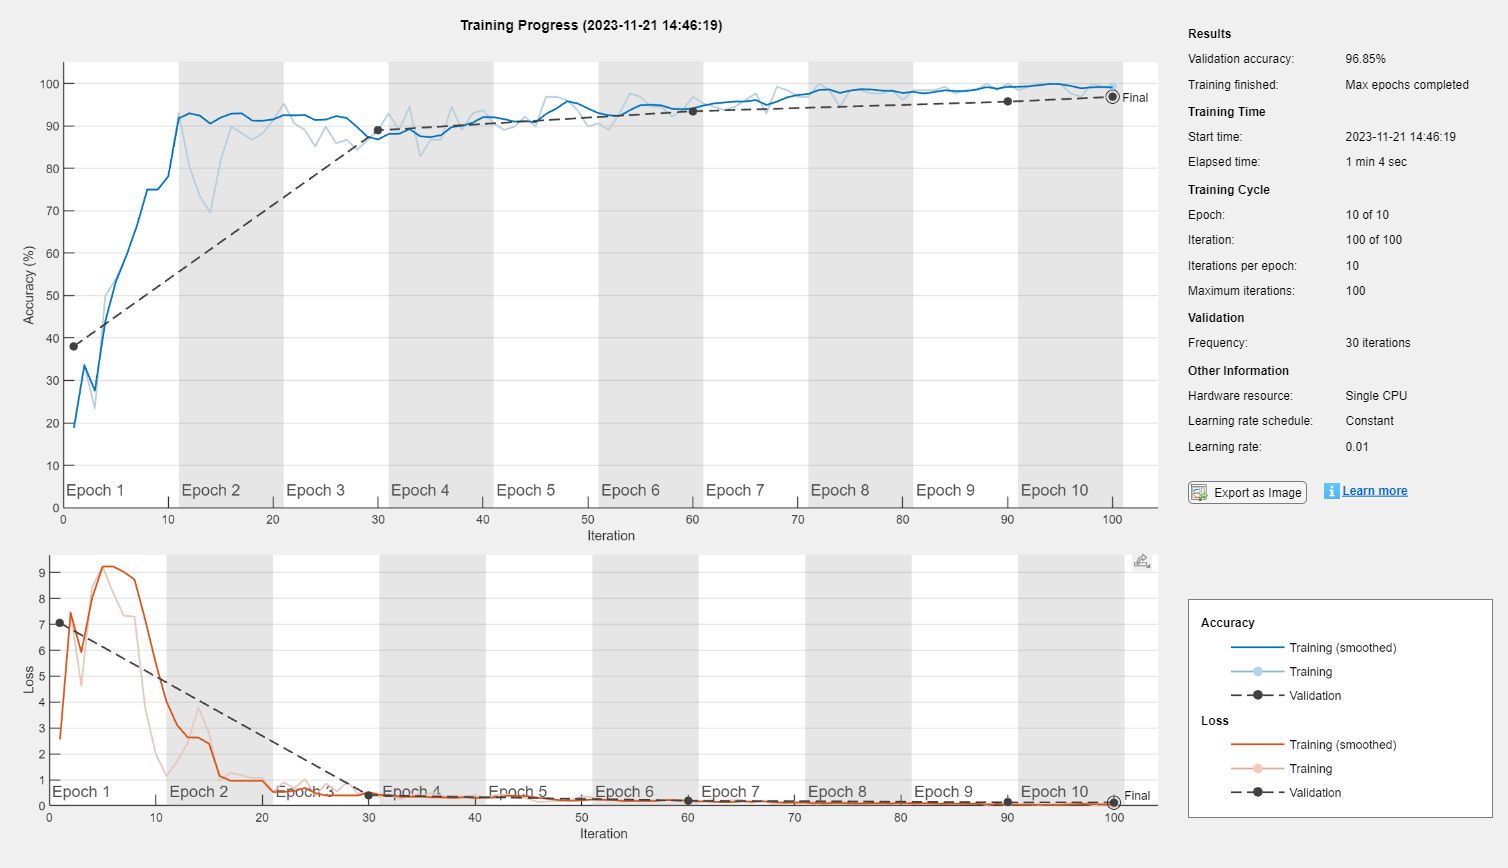

% Train the CNN

trainingStartTime = tic;

% Train the neural network
net = trainNetwork(trainImages, trainLabels, layers, options);


% Stop the timer
trainingTime = toc(trainingStartTime);

% Display the training time
fprintf('Training time: %.2f seconds\n', trainingTime);

Training time: 78.36 seconds



% save CNN model
save('trainedCNN.mat', 'net');

% Classify Test Images
predictedLabels = classify(net, testImages);

% Calculate the Accuracy
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

Test Accuracy: 96.85%


% Calculate precision, recall, and F1-score
confusionMatrix = confusionmat(testLabels, predictedLabels)

confusionMatrix =     62     0     0     0     0     1     0
     0    61     0     0     2     0     0
     0     0    64     0     0     0     0
     1     0     0    62     0     0     0
     0     0     0     0    60     3     0
     0     0     0     1     0    63     0
     0     0     0     2     1     3    58



truePositive = confusionMatrix(1, 1);
falsePositive = confusionMatrix(2, 1);
falseNegative = confusionMatrix(1, 2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f\n', precision);

Precision: 1.00


fprintf('Recall: %.2f\n', recall);

Recall: 1.00


fprintf('F1-Score: %.2f\n', f1Score);

F1-Score: 1.00


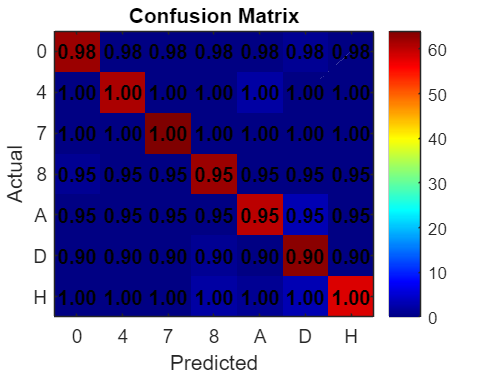

% Visualize the confusion matrix using imagesc and annotate precision
figure;
imagesc(confusionMatrix);
colorbar;
colormap('jet'); % You can change the colormap as needed
title('Confusion Matrix');
xlabel('Predicted');
ylabel('Actual');
xticks(1:numel(categories));
xticklabels(categories);
yticks(1:numel(categories));
yticklabels(categories);

% Calculate and annotate precision for each class
for i = 1:numel(categories)
    for j = 1:numel(categories)
        precision = confusionMatrix(i, i) / sum(confusionMatrix(:, i));
       text(j, i, sprintf('%.2f', precision), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'k', 'FontWeight', 'bold');
    end
end

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       13.28% |       21.85% |       2.5653 |       4.9162 |          0.0100 |
|       3 |          30 |       00:00:18 |       96.09% |       90.99% |       0.1231 |       0.2368 |          0.0100 |
|       5 |          50 |       00:00:28 |       96.09% |       97.07% |       0.1541 |       0.1341 |          0.0100 |
|=========================================================================================

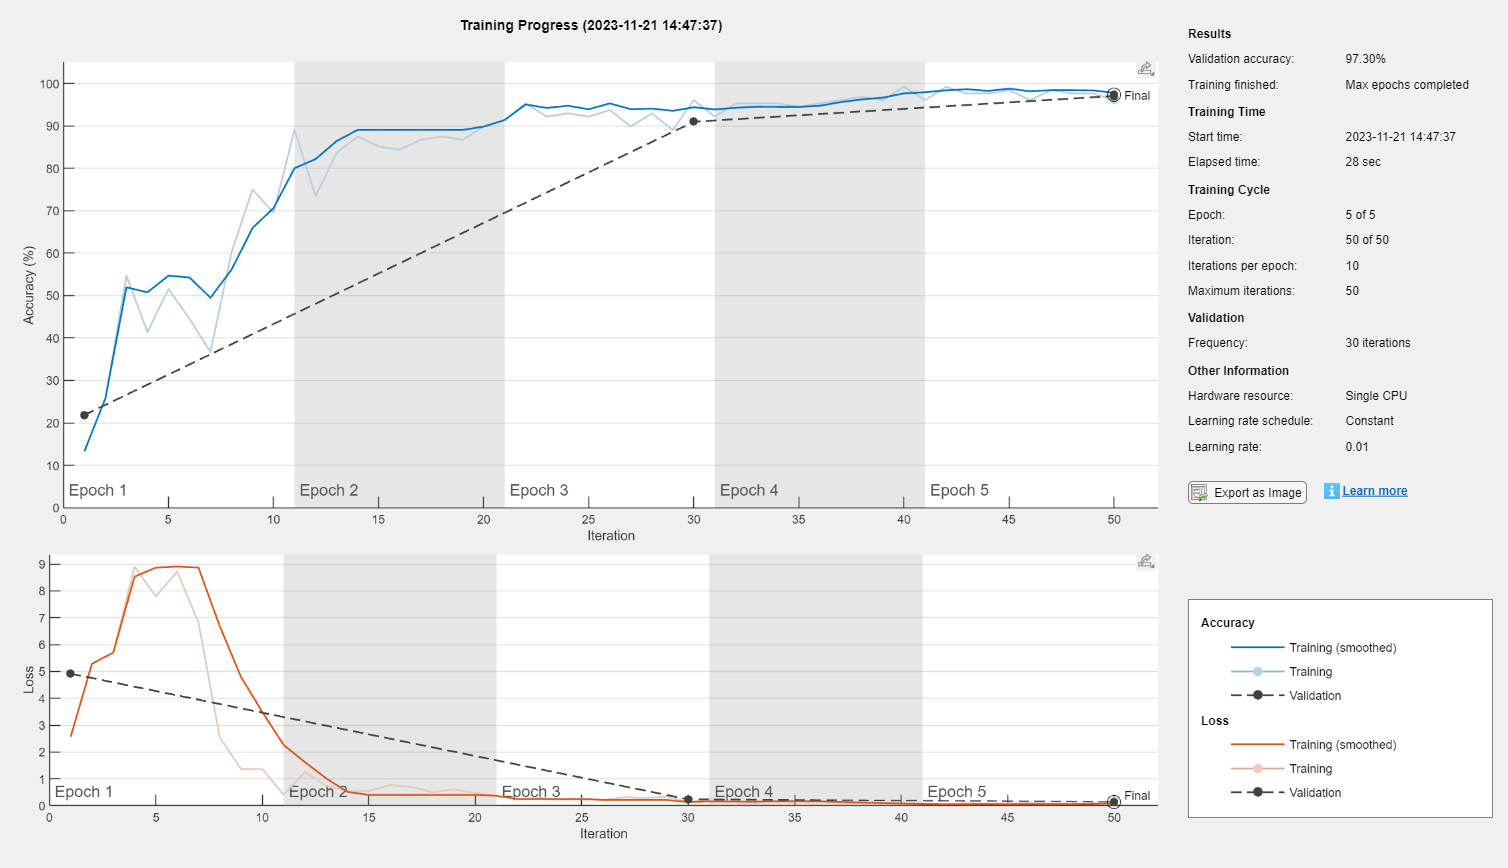

Test Accuracy for 5 Epochs: 97.30%


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       10.16% |       38.51% |       2.5570 |       3.8204 |          0.0100 |
|       3 |          30 |       00:00:16 |       96.88% |       94.59% |       0.1199 |       0.1750 |          0.0100 |
|       5 |          50 |       00:00:26 |       96.88% |              |       0.1212 |              |          0.0100 |
|       6 |          60 |       00:00:31 |      100.00% |       95.95% |       0.0264 |   

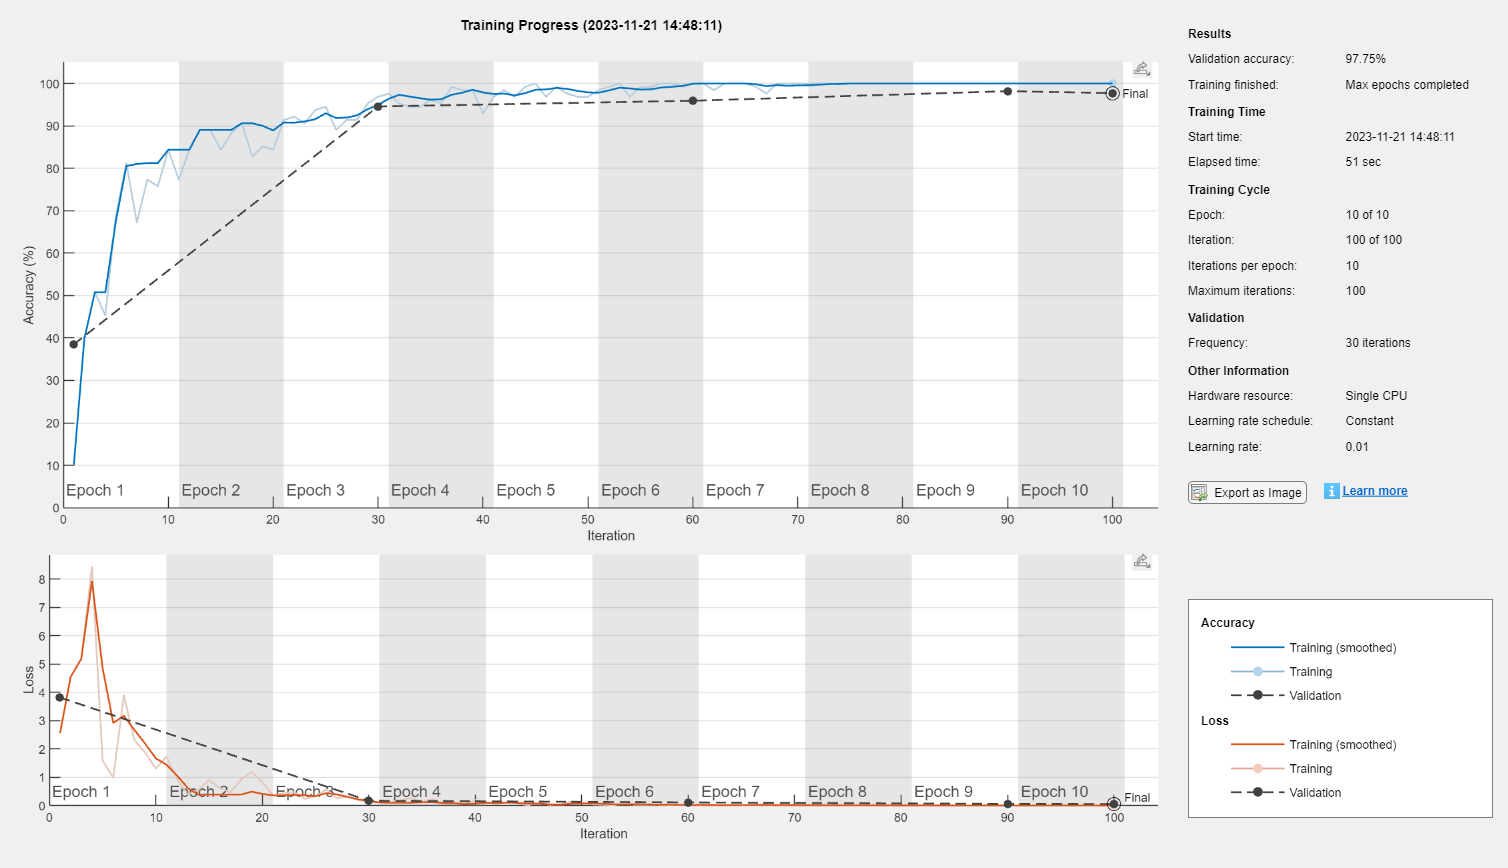

Test Accuracy for 10 Epochs: 97.75%


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       13.28% |       23.20% |       2.9228 |       5.1634 |          0.0100 |
|       3 |          30 |       00:00:16 |       96.09% |       92.79% |       0.1380 |       0.2214 |          0.0100 |
|       5 |          50 |       00:00:26 |       99.22% |              |       0.0356 |              |          0.0100 |
|       6 |          60 |       00:00:31 |      100.00% |       96.40% |       0.0211 |   

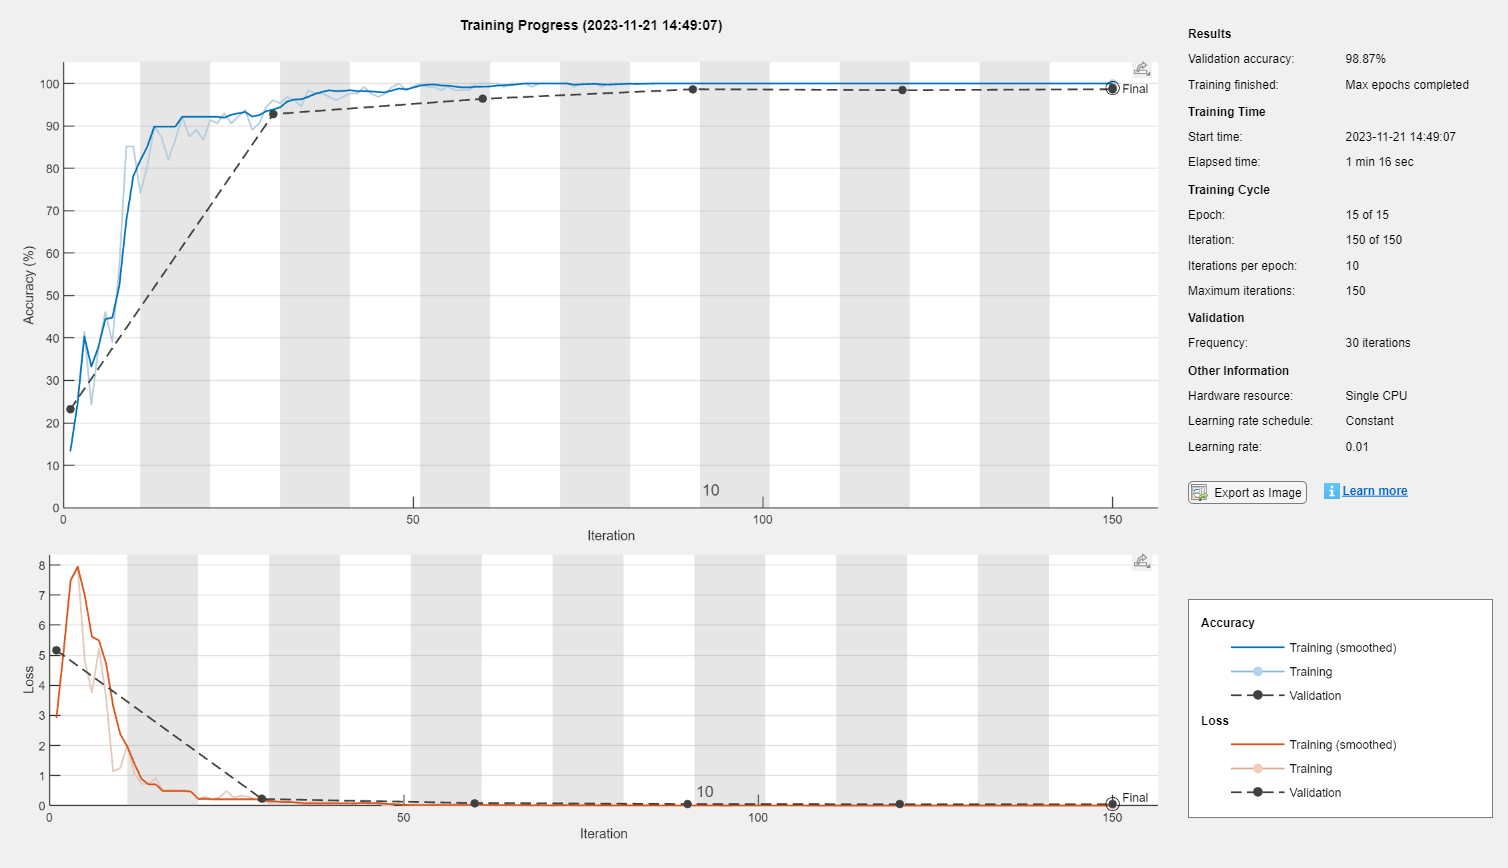

Test Accuracy for 15 Epochs: 98.87%


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       21.09% |       28.38% |       2.3195 |       3.8634 |          0.0100 |
|       3 |          30 |       00:00:16 |       94.53% |       91.22% |       0.2595 |       0.3194 |          0.0100 |
|       5 |          50 |       00:00:25 |       96.88% |              |       0.1023 |              |          0.0100 |
|       6 |          60 |       00:00:31 |       96.88% |       96.17% |       0.0839 |   

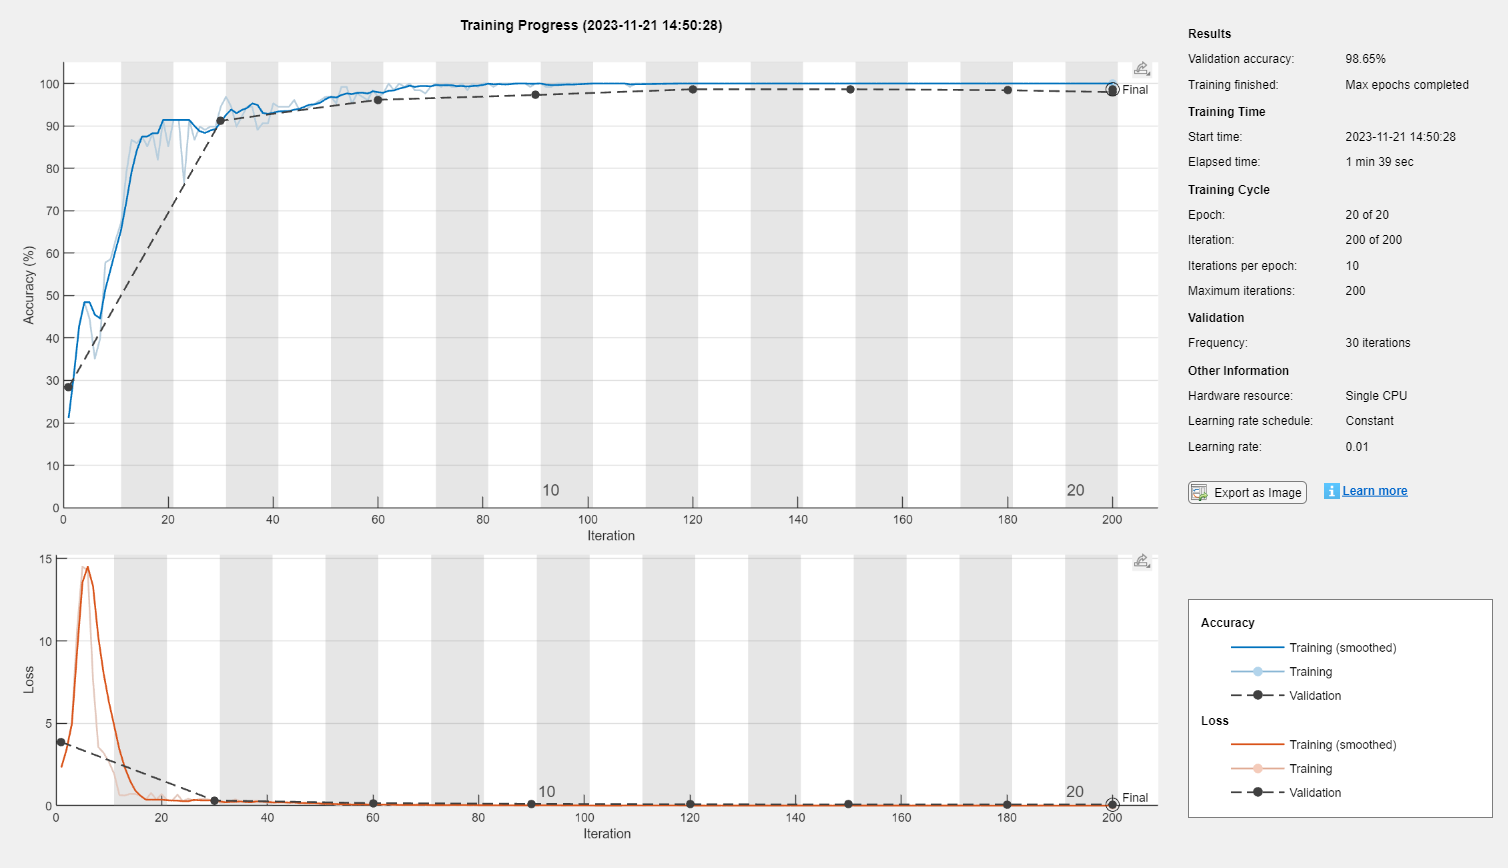

Test Accuracy for 20 Epochs: 98.65%


% Hyperparameter tuning for the number of epochs
numEpochsList = [5, 10, 15, 20]; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
EpochsAccuracyMatrix = zeros(length(numEpochsList), 1);
% Initialize a matrix to store training for each number of epochs
EpochsTime = zeros(length(numEpochsList), 1);

for idx = 1:length(numEpochsList)
    currentNumEpochs = numEpochsList(idx);

    % Update the MaxEpochs parameter in trainingOptions
    options.MaxEpochs = currentNumEpochs;
    
    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    EpochsAccuracyMatrix(idx) = accuracy;
    EpochsTime(idx) = trainingTime;

    fprintf('Test Accuracy for %d Epochs: %.2f%%\n', currentNumEpochs, accuracy * 100);
end

% Plot the accuracy performance
figure;

bar(numEpochsList, EpochsAccuracyMatrix);

ylim([0.9, 1]); 
xlabel('Number of Epochs');
ylabel('Accuracy');
title('Accuracy Performance vs Number of Epochs');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/epochs.eps'

eps_filename = 'results/epochs.eps'

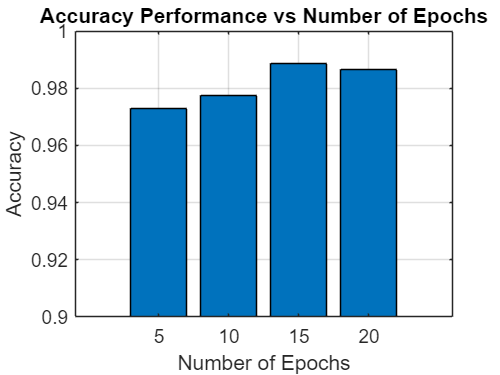

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/epochs.eps


% Plot the training time
figure;

bar(numEpochsList, EpochsTime);

xlabel('Number of Epochs');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Number of Epochs');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/epochs_trainingtime.eps'

eps_filename = 'results/epochs_trainingtime.eps'

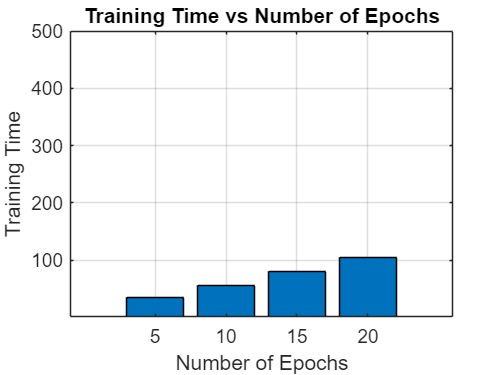

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/epochs_trainingtime.eps


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       26.56% |       35.14% |       2.7204 |       3.9127 |          0.0100 |
|       3 |          30 |       00:00:17 |       94.53% |       93.69% |       0.1843 |       0.2265 |          0.0100 |
|       5 |          50 |       00:00:26 |       99.22% |              |       0.0151 |              |          0.0100 |
|       6 |          60 |       00:00:31 |      100.00% |       97.52% |       0.0144 |   

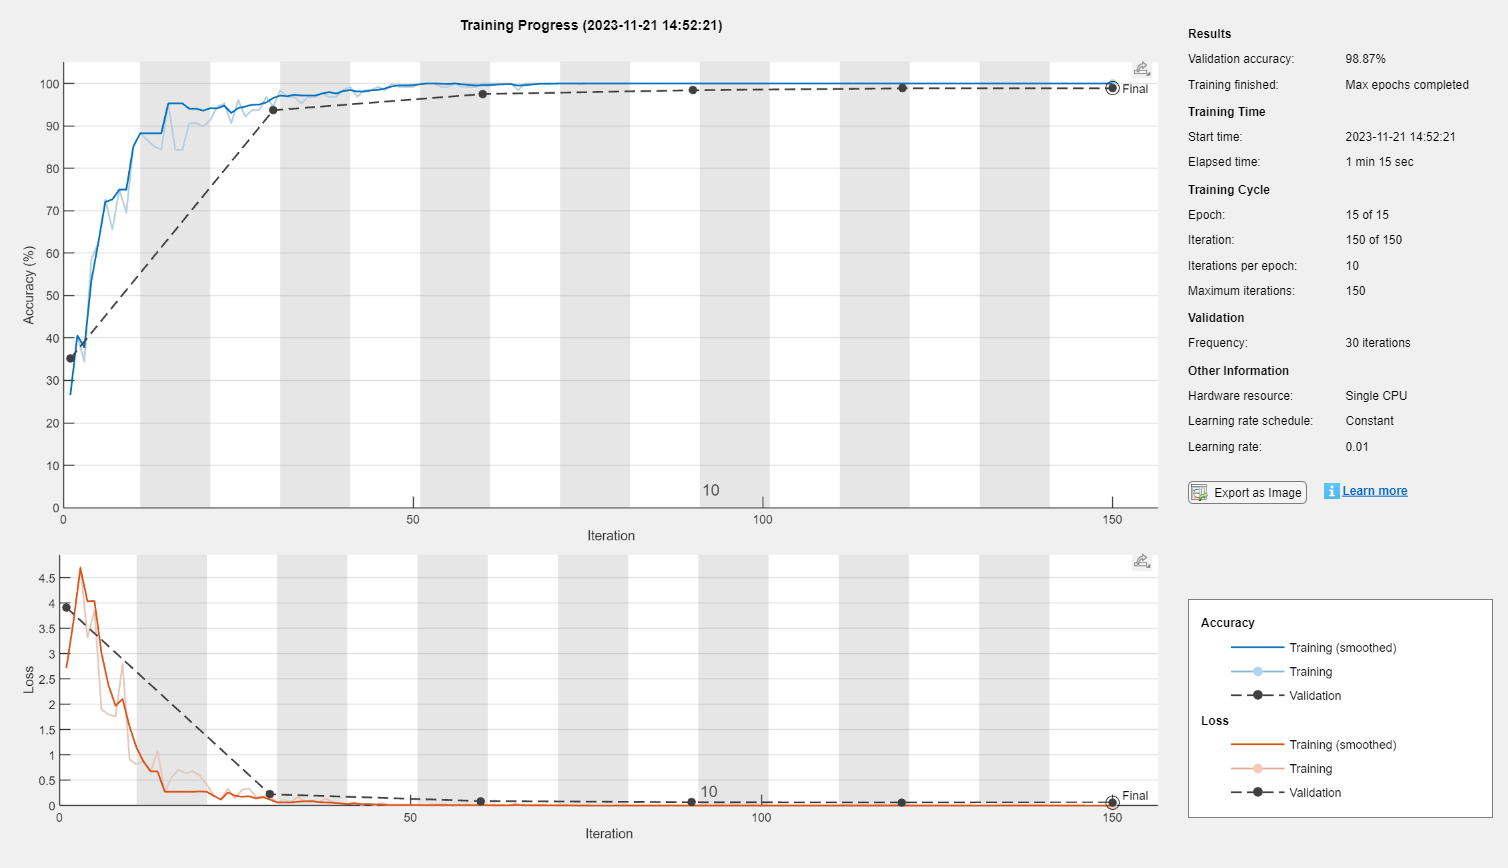

Test Accuracy for 1.000000e-02 Learning Rate: 98.87%


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       14.06% |       23.42% |       2.7943 |       2.3296 |          0.0010 |
|       3 |          30 |       00:00:18 |       96.88% |       92.79% |       0.1328 |       0.2186 |          0.0010 |
|       5 |          50 |       00:00:27 |       99.22% |              |       0.0538 |              |          0.0010 |
|       6 |          60 |       00:00:33 |      100.00% |       97.30% |       0.0349 |   

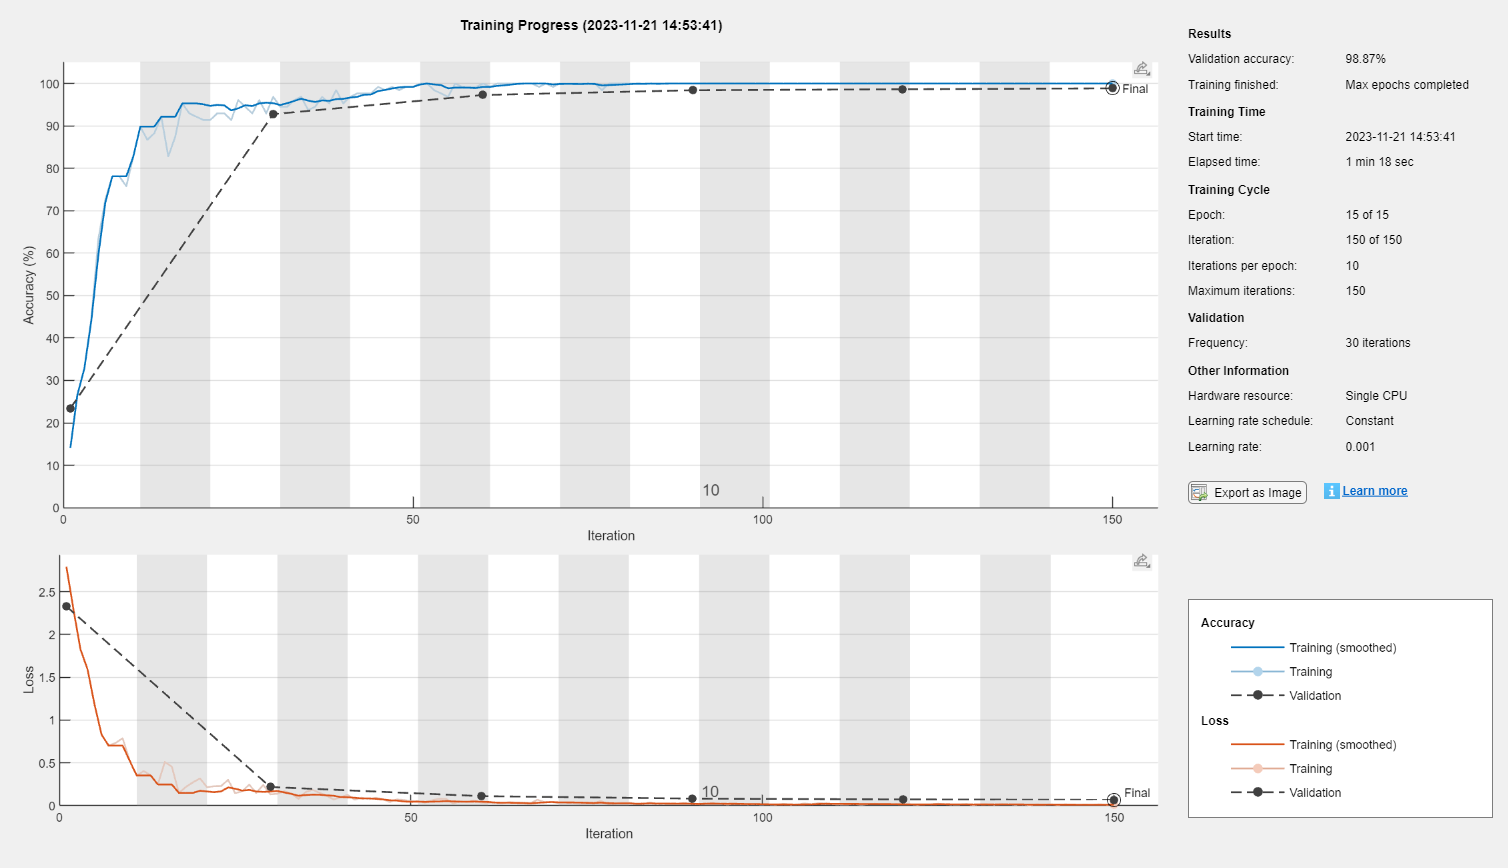

Test Accuracy for 1.000000e-03 Learning Rate: 98.87%


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       10.94% |       14.41% |       2.5042 |       2.4422 |      1.0000e-04 |
|       3 |          30 |       00:00:16 |       84.38% |       81.76% |       0.6292 |       0.7046 |      1.0000e-04 |
|       5 |          50 |       00:00:26 |       88.28% |              |       0.4736 |              |      1.0000e-04 |
|       6 |          60 |       00:00:31 |       88.28% |       86.49% |       0.3918 |   

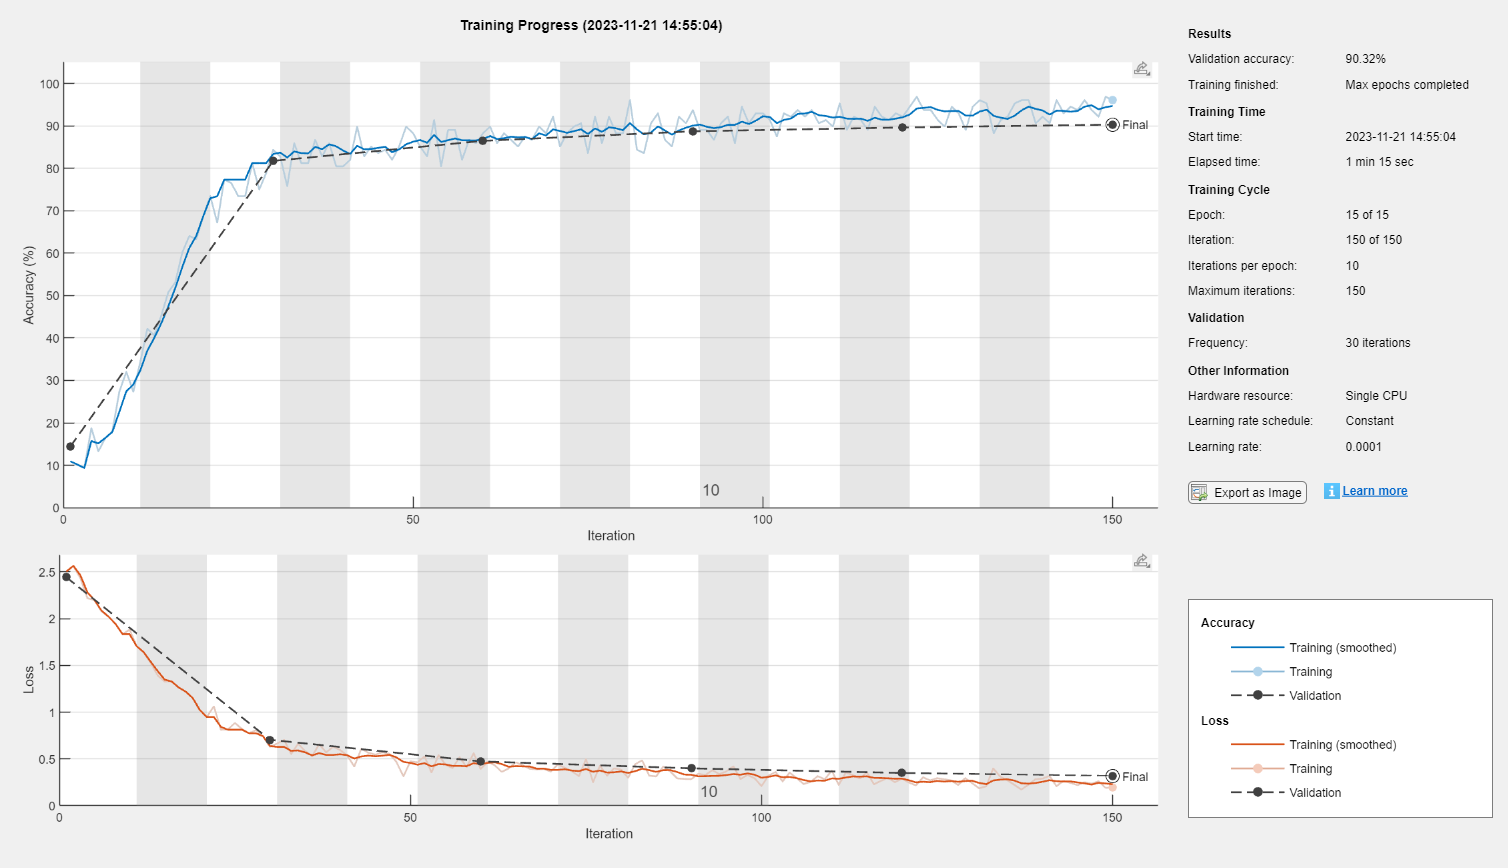

Test Accuracy for 1.000000e-04 Learning Rate: 90.32%


% Hyperparameter tuning for the number of learning rates
learningRates = [0.01, 0.001, 0.0001]; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
LRaccuracyMatrix = zeros(length(learningRates), 1);
LRTrainingTime = zeros(length(learningRates), 1);

for idx = 1:length(learningRates)
    currentlearningRate = learningRates(idx);

    % Update the MaxEpochs parameter in trainingOptions
    options.InitialLearnRate = currentlearningRate;
    options.MaxEpochs = 15;

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    LRaccuracyMatrix(idx) = accuracy;
    LRTrainingTime(idx) = trainingTime;

    fprintf('Test Accuracy for %d Learning Rate: %.2f%%\n', currentlearningRate, accuracy * 100);
end

% Plot the accuracy performance
learningRates = {'0.01', '0.001','0.0001'};
learningRateValues = [1, 2, 3];
figure;

% bar(learningRates, LRaccuracyMatrix);
bar(learningRateValues, LRaccuracyMatrix);
xticks(learningRateValues);
xticklabels(learningRates);

xlabel('Learning Rates');
ylabel('Accuracy');
ylim([0.9, 1]); 

title('Accuracy Performance vs Learning Rates');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/learning_rate_accuracy.eps'

eps_filename = 'results/learning_rate_accuracy.eps'

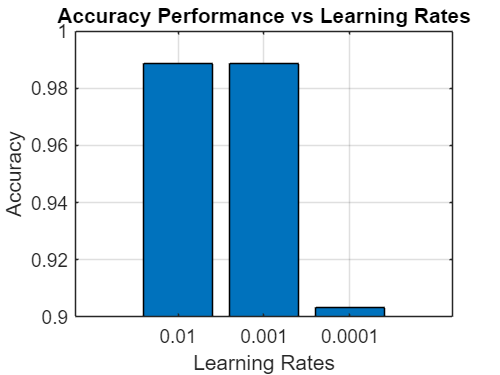

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/learning_rate_accuracy.eps


% Plot the accuracy performance
learningRates = {'0.01', '0.001','0.0001'};
learningRateValues = [1, 2, 3];
figure;

% bar(learningRates, LRaccuracyMatrix);
bar(learningRateValues, LRTrainingTime);
xticks(learningRateValues);
xticklabels(learningRates);

xlabel('Learning Rates');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Learning Rates');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/learning_rate_trainingtime.eps'

eps_filename = 'results/learning_rate_trainingtime.eps'

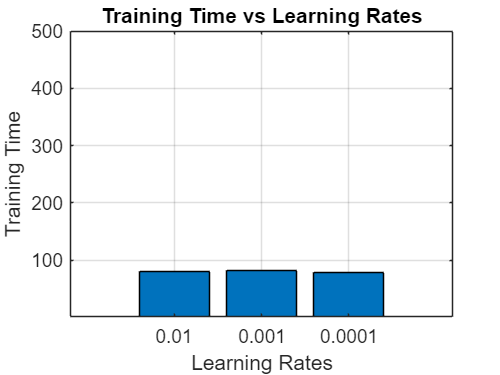

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/learning_rate_trainingtime.eps


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       16.41% |       48.87% |       2.5717 |       3.7912 |          0.0100 |
|       3 |          30 |       00:00:16 |       91.41% |       91.89% |       0.3008 |       0.2554 |          0.0100 |
|       5 |          50 |       00:00:26 |       96.09% |              |       0.1272 |              |          0.0100 |
|       6 |          60 |       00:00:31 |      100.00% |       98.42% |       0.0192 |   

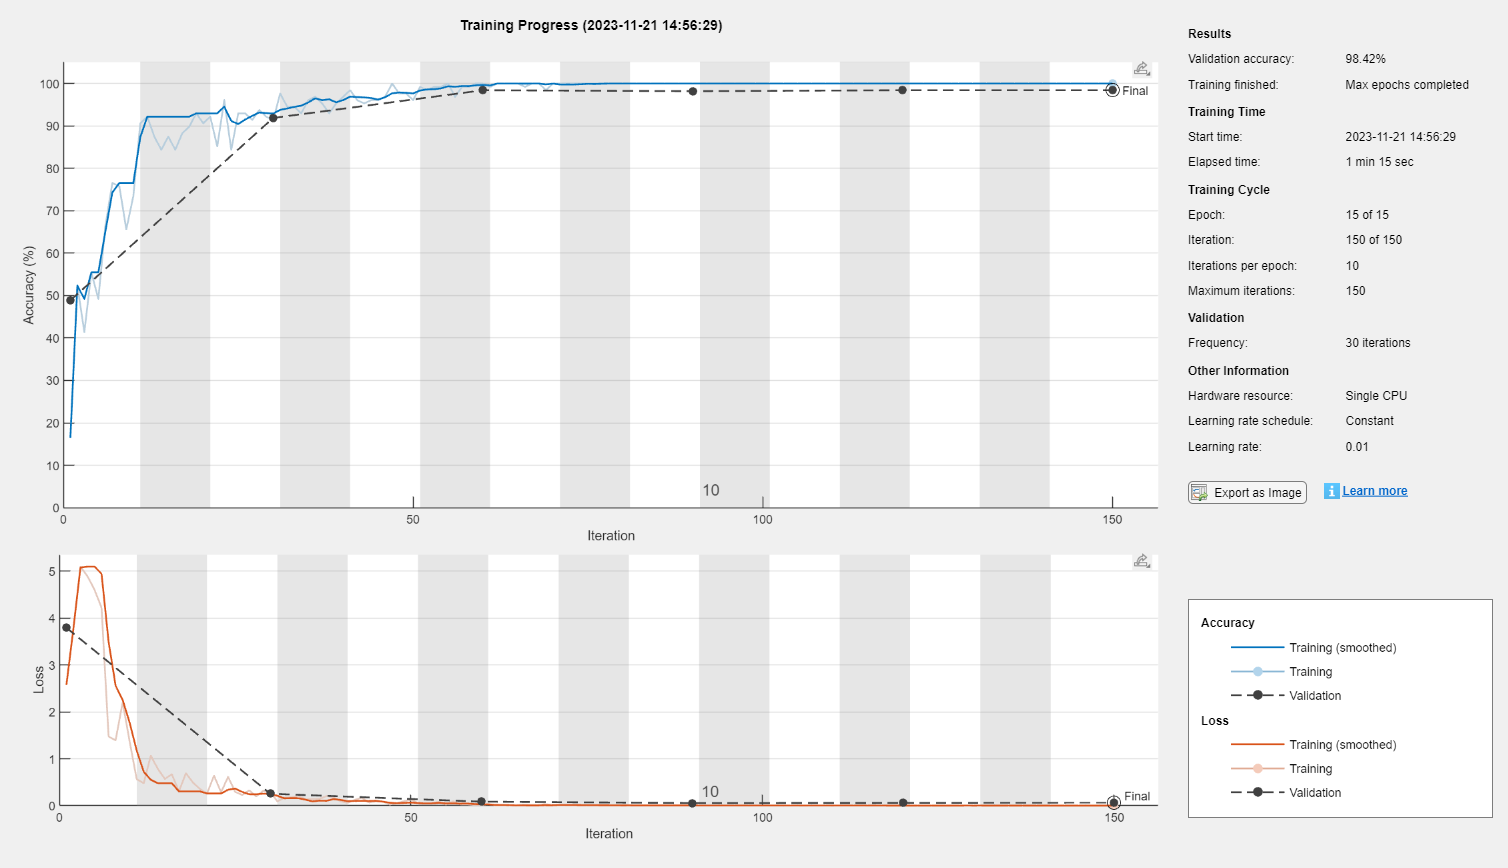

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       17.19% |       68.92% |       2.6595 |      20.9126 |          0.0100 |
|       3 |          30 |       00:00:16 |       85.94% |       90.99% |       2.7117 |       1.1174 |          0.0100 |
|       5 |          50 |       00:00:25 |       96.09% |              |       0.3663 |              |          0.0100 |
|       6 |          60 |       00:00:30 |       98.44% |       97.30% |       0.0345 |   

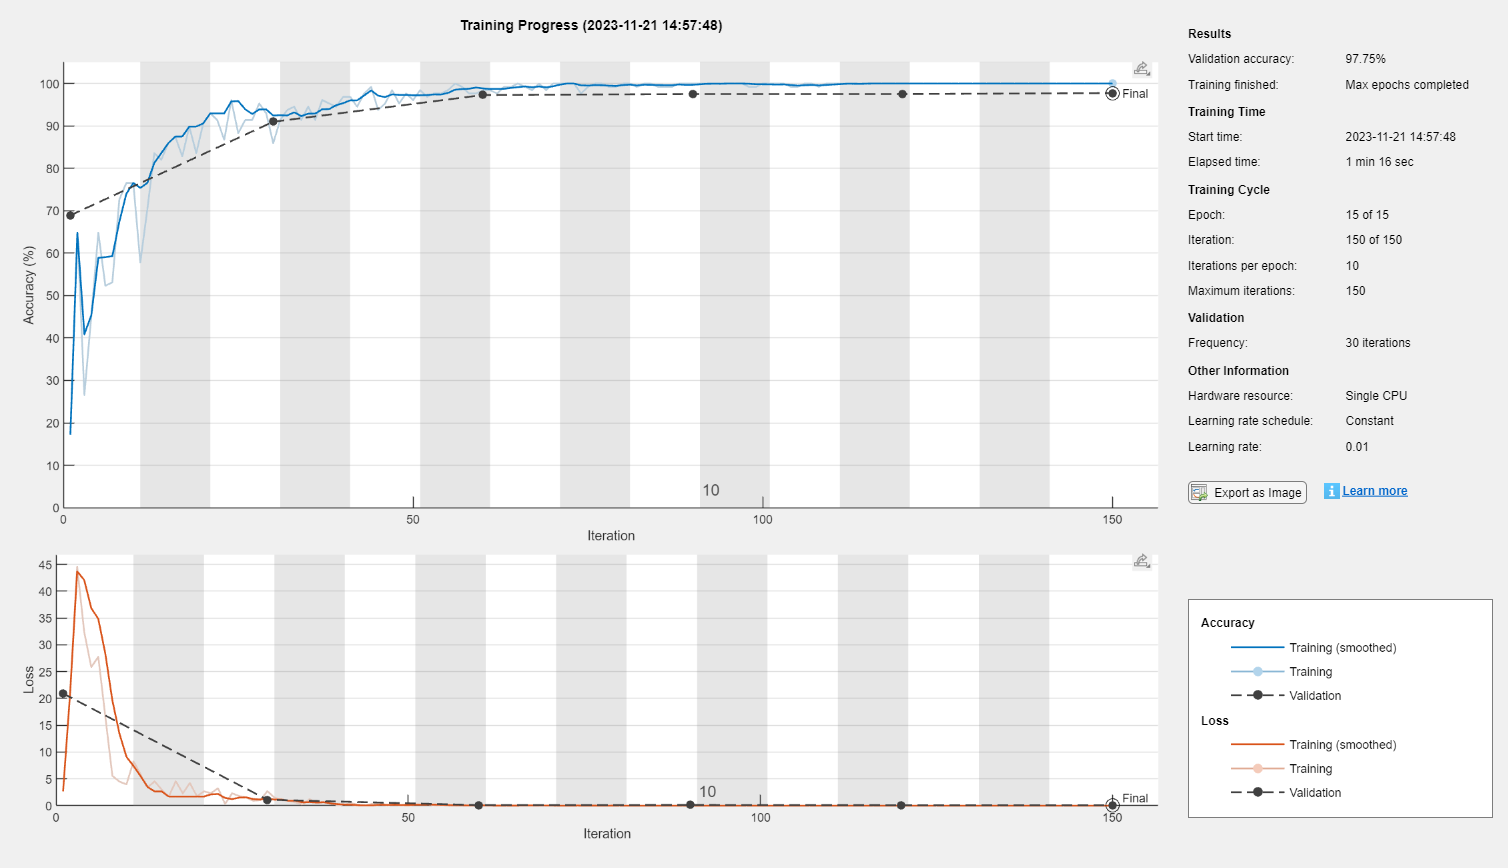

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       22.66% |       29.95% |       2.6184 |     136.2048 |          0.0100 |
|       3 |          30 |       00:00:16 |       83.59% |       91.67% |       2.2580 |       0.9953 |          0.0100 |
|       5 |          50 |       00:00:26 |      100.00% |              |       0.0037 |              |          0.0100 |
|       6 |          60 |       00:00:31 |       92.97% |       93.69% |       1.2950 |   

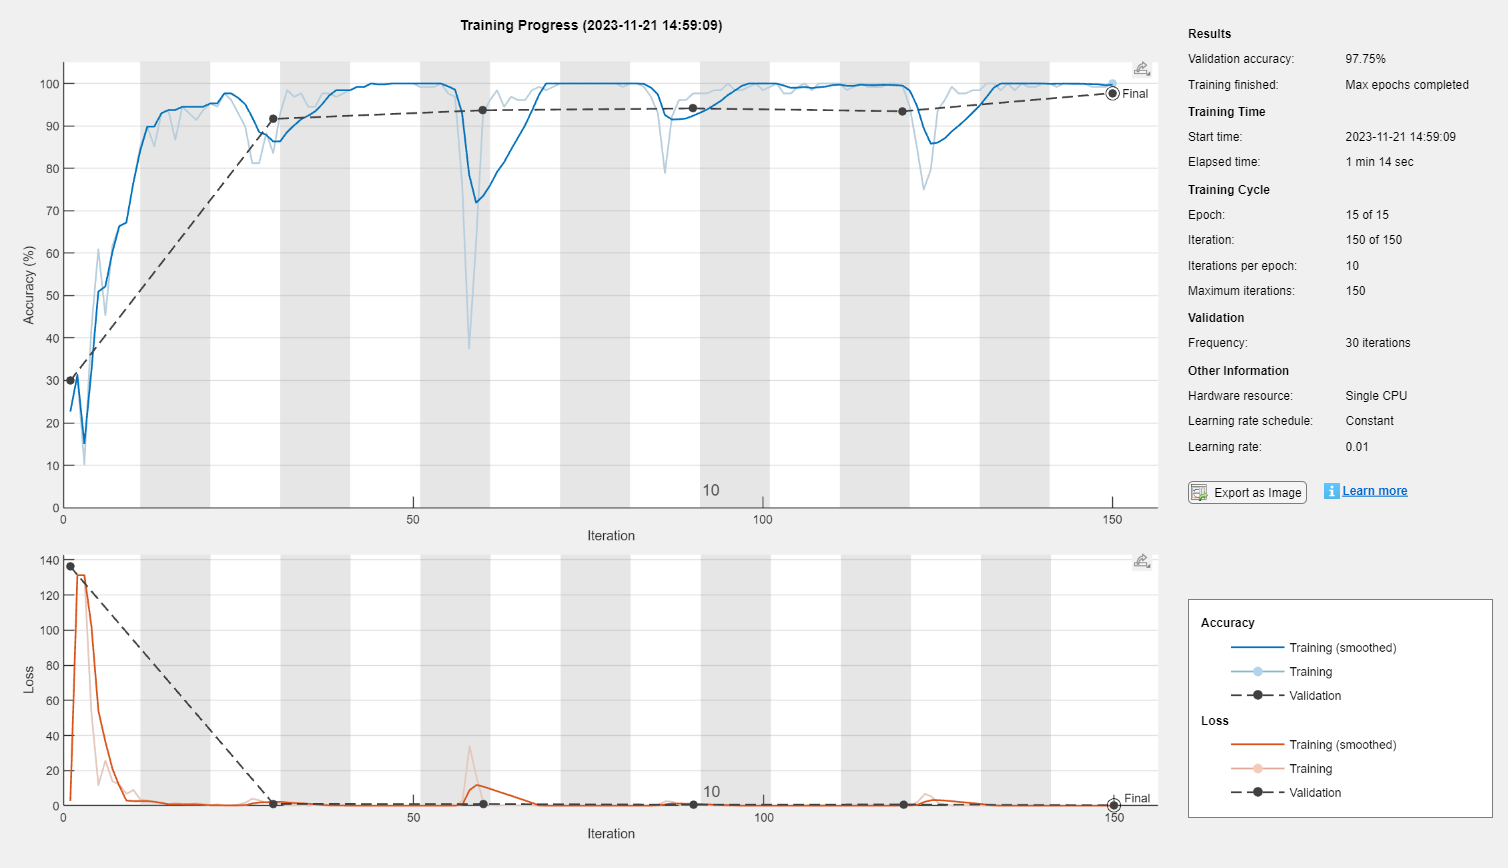

% Hyperparameter tuning for the number of epochs
optimizers = {'sgdm', 'adam', 'rmsprop'}; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
OaccuracyMatrix = zeros(length(optimizers), 1);
OTrainingTime = zeros(length(optimizers), 1);

for idx = 1:length(optimizers)
    currentoptimizer = optimizers(idx);

    options = trainingOptions( ...
    currentoptimizer, ... % Stochastic Gradient Descent with Momentum
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 15, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

    % Update the MaxEpochs parameter in trainingOptions
    % options.InitialLearnRate = currentlearningRate;
    % options.MaxEpochs = 15;
    % options.InitialLearnRate = 0.01;

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    OaccuracyMatrix(idx) = accuracy;
    OTrainingTime(idx) = trainingTime;

    % fprintf('Test Accuracy for %s Learning Rate: %.2f%%\n', currentoptimizer, accuracy * 100);
end

% Plot the accuracy performance
figure;
bar(OaccuracyMatrix);
xticks([1 2 3]);
xticklabels(optimizers);
xlabel('Optimizers');
ylabel('Accuracy');
ylim([0.9, 1]); 
title('Accuracy Performance vs Optimizers');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/optimiser.eps'

eps_filename = 'results/optimiser.eps'

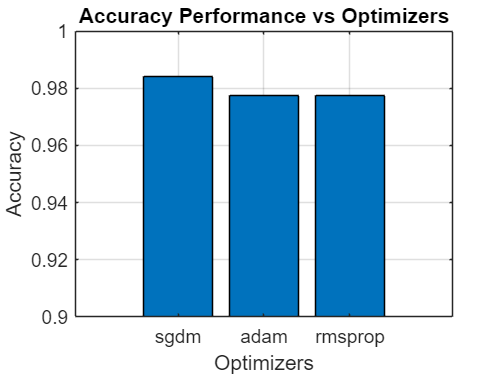

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/optimiser.eps


% Plot the training time
figure;

bar(OTrainingTime);
xticks([1 2 3]);
xticklabels(optimizers);

xlabel('Optimizers');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Optimizers');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/optimiser_trainingtime.eps'

eps_filename = 'results/optimiser_trainingtime.eps'

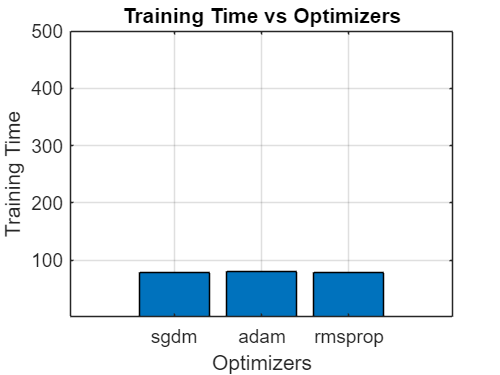

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/optimiser_trainingtime.eps


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       12.50% |       26.35% |       2.4753 |       7.2069 |          0.0100 |
|       1 |          30 |       00:00:05 |       12.50% |       14.19% |       1.9501 |       1.9469 |          0.0100 |
|       1 |          50 |       00:00:06 |       12.50% |              |       1.9639 |              |          0.0100 |
|       1 |          60 |       00:00:07 |        0.00% |       14.19% |       1.9655 |   

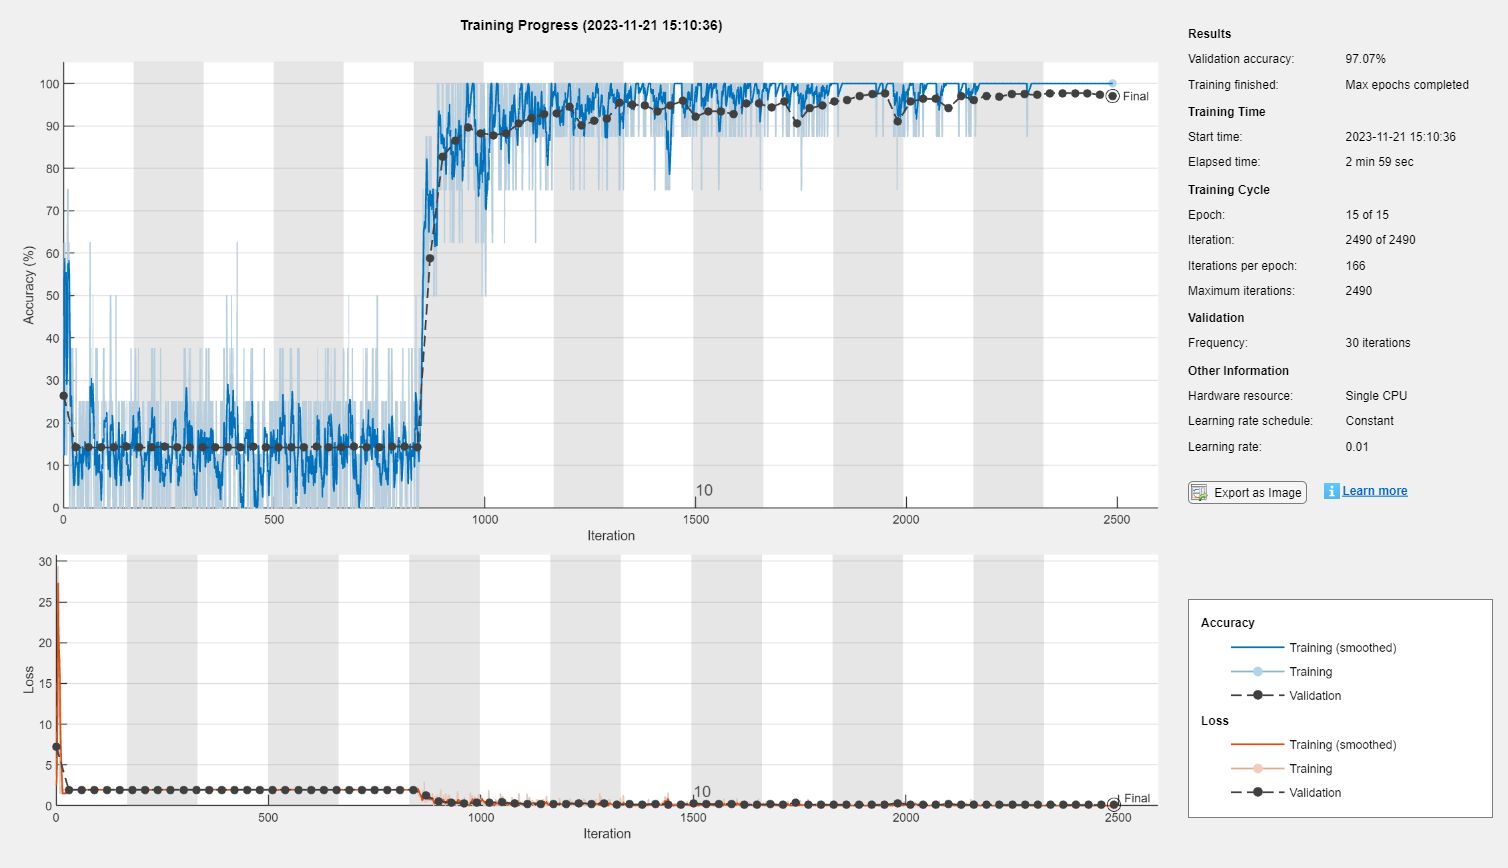

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        6.25% |       14.64% |       3.1439 |       7.5239 |          0.0100 |
|       1 |          30 |       00:00:07 |       87.50% |       87.39% |       0.3432 |       0.4231 |          0.0100 |
|       1 |          50 |       00:00:09 |       87.50% |              |       0.2728 |              |          0.0100 |
|       1 |          60 |       00:00:11 |      100.00% |       88.96% |       0.1807 |   

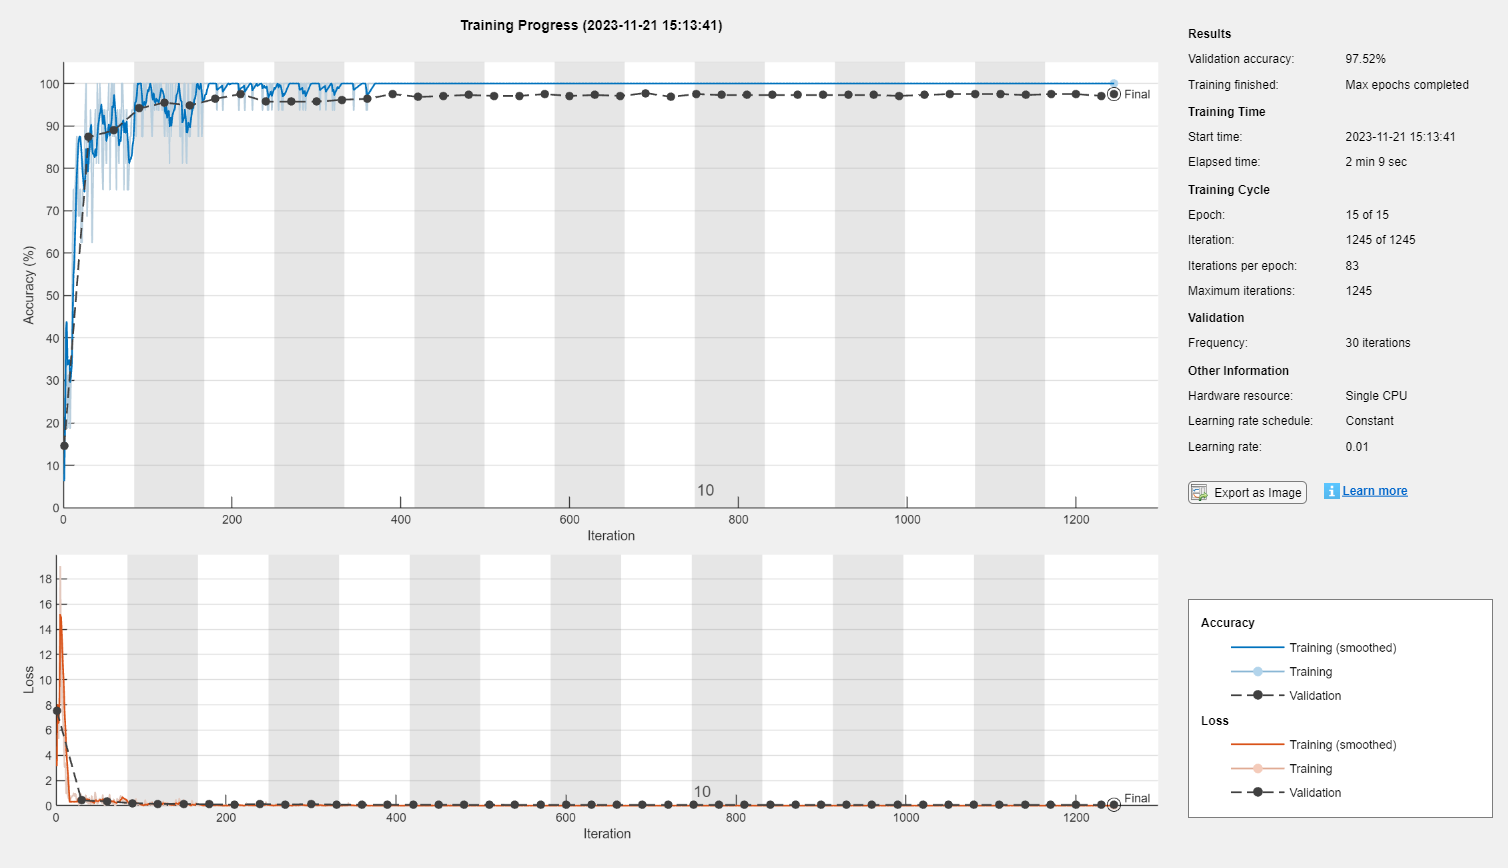

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |        9.38% |       31.08% |       2.3488 |       3.3944 |          0.0100 |
|       1 |          30 |       00:00:07 |       81.25% |       87.61% |       1.0391 |       0.6638 |          0.0100 |
|       2 |          50 |       00:00:10 |       87.50% |              |       0.2941 |              |          0.0100 |
|       2 |          60 |       00:00:11 |       96.88% |       90.99% |       0.0456 |   

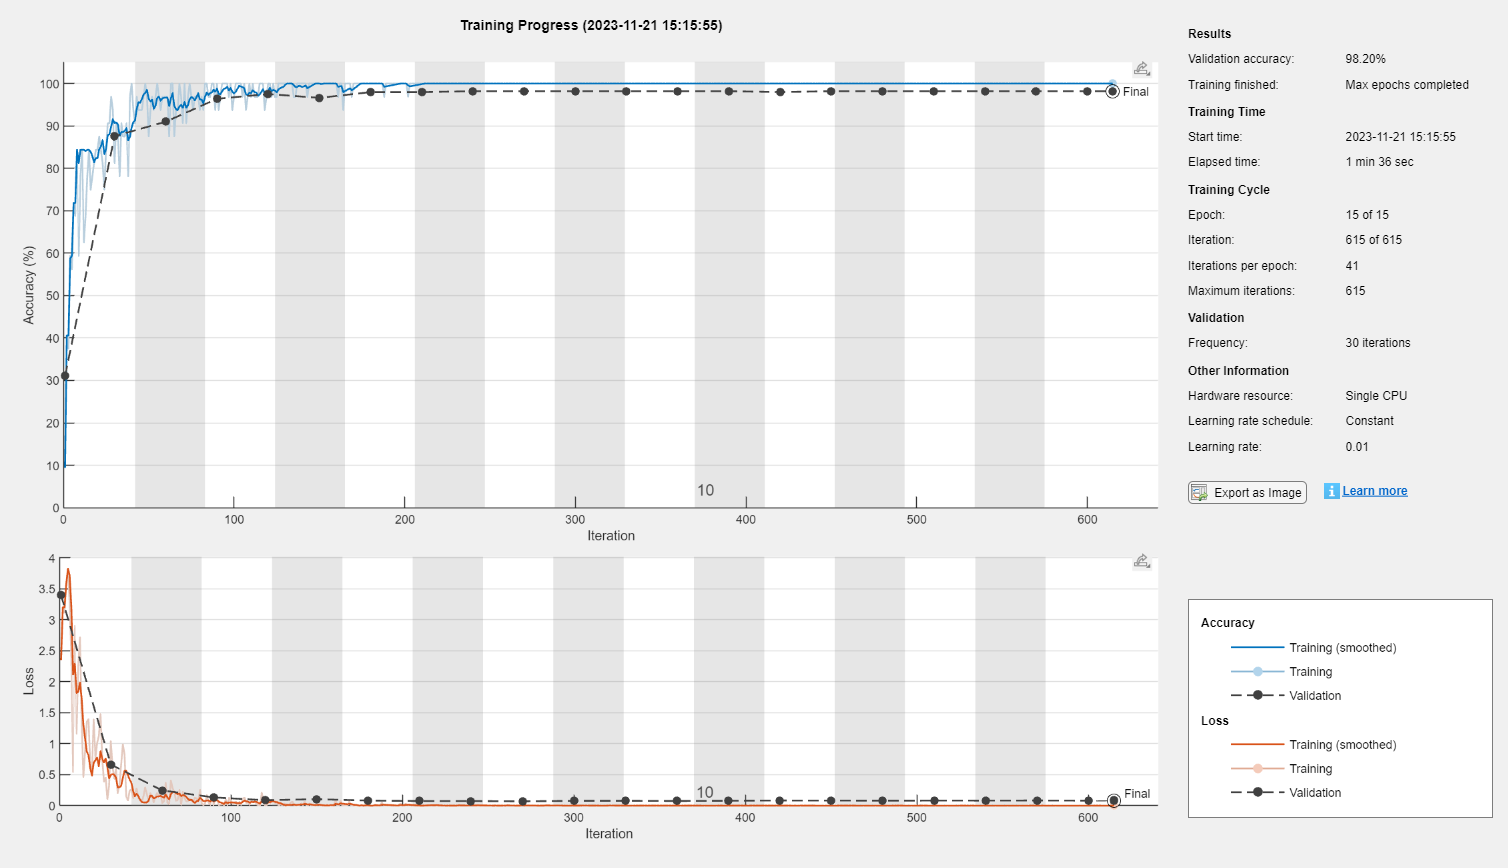

% Hyperparameter tuning for the number of epochs
batch_size = [8,16,32]; % You can modify this list according to your requirements

% Initialize a matrix to store accuracy for each number of epochs
batchaccuracyMatrix = zeros(length(batch_size), 1);
batchTrainingTime = zeros(length(batch_size), 1);

for idx = 1:length(batch_size)
    currentbatch_size = batch_size(idx);

    options = trainingOptions( ...
    'sgdm', ... % Stochastic Gradient Descent with Momentum
    'MiniBatchSize', currentbatch_size, ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 15, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

    % Update the MaxEpochs parameter in trainingOptions
    % options.InitialLearnRate = currentlearningRate;
    % options.MaxEpochs = 15;
    % options.InitialLearnRate = 0.01;

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    batchaccuracyMatrix(idx) = accuracy;
    batchTrainingTime(idx) = trainingTime;

    % fprintf('Test Accuracy for %s Learning Rate: %.2f%%\n', currentoptimizer, accuracy * 100);
end

% Plot the accuracy performance
batch_size = [8,16,32];
figure;
bar(batch_size, batchaccuracyMatrix);
xlabel('Batch Size');
ylabel('Accuracy');
ylim([0.9, 1]); 
title('Accuracy Performance vs Batch Size');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/batchsize.eps';
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Plot the training time
figure;
bar(batch_size, batchTrainingTime);

xlabel('Batch Size');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Batch Size');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/batch_size_trainingtime.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Constants
numConvLayersList = [2, 3, 4]; % Vary the number of convolution layers
numConfigs = numel(numConvLayersList);
LayersaccuracyResults = zeros(numConfigs, 1);
LayersTrainingTime = zeros(numConfigs, 1);

% Loop through different configurations
for i = 1:numConfigs
    % Define the neural network architecture with varying convolution layers
    layers = [
        imageInputLayer([imageSize 1])
    ];
    
    for j = 1:numConvLayersList(i)
        layers = [layers
            convolution2dLayer(3, 16, 'Padding', 'same')
            batchNormalizationLayer
            reluLayer
            maxPooling2dLayer(2, 'Stride', 2)
        ];
    end
    
    layers = [layers
        fullyConnectedLayer(numel(categories))
        softmaxLayer
        classificationLayer
    ];

    % Set training options
    options = trainingOptions( ...
        'sgdm', ... % Stochastic Gradient Descent with Momentum
        'InitialLearnRate', 0.01, ...
        'MaxEpochs', 10, ...
        'Shuffle', 'every-epoch', ...
        'ValidationData', {testImages, testLabels}, ...
        'ValidationFrequency', 30, ...
        'Verbose', true, ...
        'Plots', 'training-progress' ...
        );

    trainingStartTime = tic;

    % Train the CNN
    net = trainNetwork(trainImages, trainLabels, layers, options);

    trainingTime = toc(trainingStartTime);

    % Classify Test Images
    predictedLabels = classify(net, testImages);

    % Calculate the Accuracy
    accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
    
    % Store the accuracy for this configuration
    LayersaccuracyResults(i) = accuracy;
    LayersTrainingTime(i) = trainingTime;
end


% Plot the results
figure;
bar(numConvLayersList, LayersaccuracyResults)
xlabel('Number of Convolution Layers')
ylabel('Accuracy')
ylim([0.9, 1]); 
title('Accuracy Performance vs Number of Convolution Layers')
grid on;

% Save the plot as an EPS file
eps_filename = 'results/layers.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Plot the training time
figure;
bar(numConvLayersList, LayersTrainingTime);
xticks(learningRateValues);
xticklabels(learningRates);

xlabel('Number of Convolution Layers');
ylabel('Training Time');
ylim([1, 500]); 

title('Training Time vs Number of Convolution Layers');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/layers_trainingtime.eps'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);